# Interpolation

StyleGAN lets us interpolate between faces. There are two latent spaces we can do interpolation in. First let's make the vectors that we interpolate between.

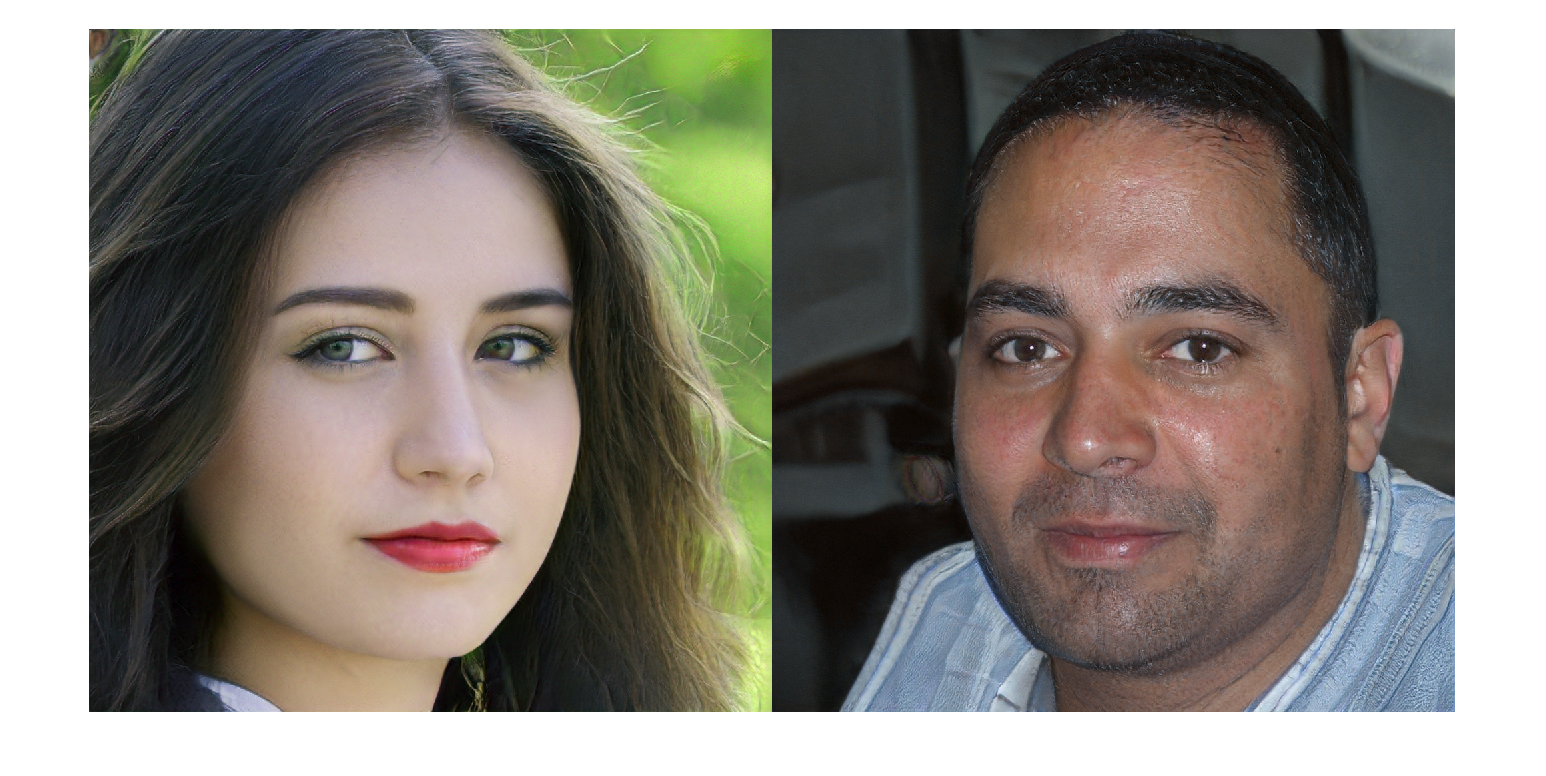

seeds = [543, 32];

filename = fullfile(projectRoot(), "weights", "ffhq.mat");
generator = stylegan.Generator(filename);
generator.NoiseMethod = @stylegan.randnCached;

rng(seeds(1));
vec1 = randn(512, 1);
z1 = dlarray(single(reshape(vec1, 1, 1, [], 1)), 'SSCB');
rng(seeds(2));
vec2 = randn(512, 1);
z2 = dlarray(single(reshape(vec2, 1, 1, [], 1)), 'SSCB');

w1 = generator.mapping(z1);
w1 = generator.applyTruncation(w1);
w2 = generator.mapping(z2);
w2 = generator.applyTruncation(w2);

out1 = generator.image(generator.synthesis(w1));
out2 = generator.image(generator.synthesis(w2));
figure;
imshowpair(out1, out2, "montage");

First linear interpolation in the first latent space

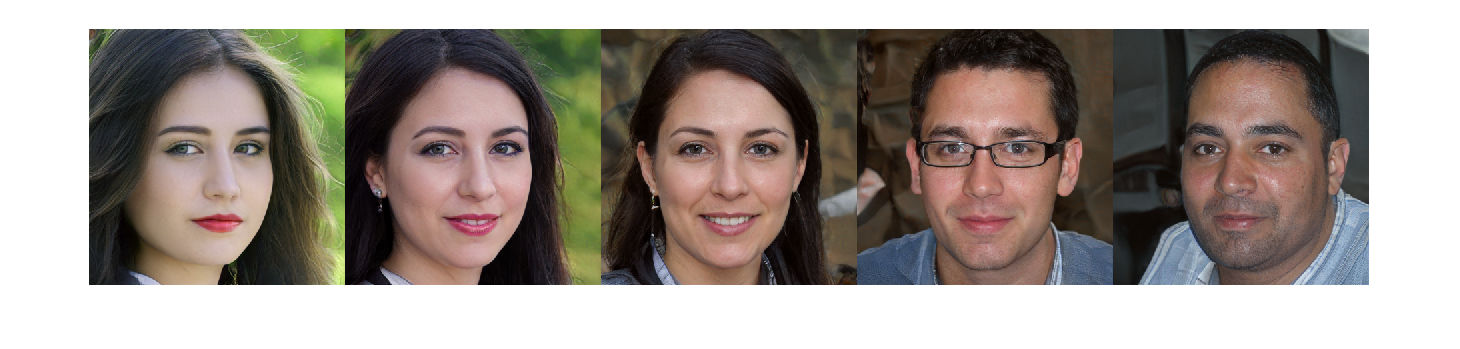

n = 5;
for iIm = 1:n
    alpha = (iIm - 1)./(n-1);
    z = (1-alpha)*z1 + alpha*z2;
    out{iIm} = generator.image(generator.generate(z));
end
montage(out, "Size", [1, n])


pathLength = calculatePerceptualPathLength(out);
fprintf("Perceptual path length = %.2e\n", pathLength)

Perceptual path length = 1.73e+05


Not so great, let's try slerp

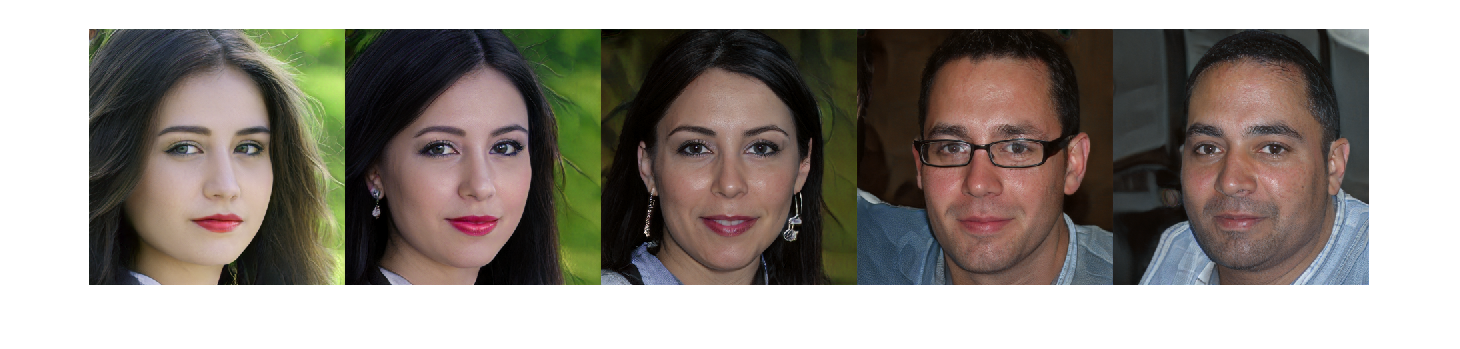

for iIm = 1:n
    alpha = (iIm - 1)./(n-1);
    z = slerp(alpha, vec1, vec2);
    z = dlarray(single(reshape(z, 1, 1, [], 1)), 'SSCB');
    out{iIm} = generator.image(generator.generate(z));
end
montage(out, "Size", [1, n])


pathLength = calculatePerceptualPathLength(out);
fprintf("Perceptual path length = %.2e\n", pathLength)

Perceptual path length = 1.69e+05


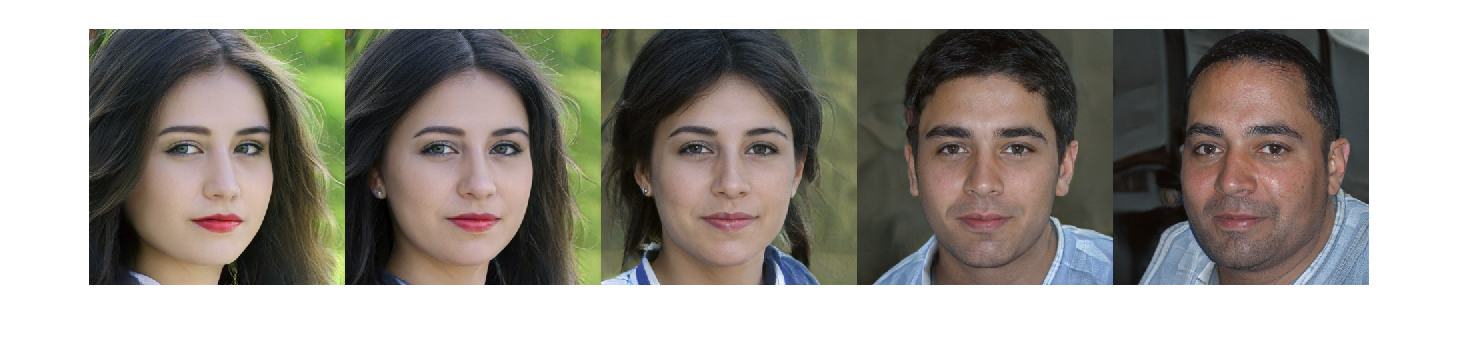

for iIm = 1:n
    alpha = (iIm - 1)./(n-1);
    w = (1-alpha)*w1 + alpha*w2;
    out{iIm} = generator.image(generator.synthesis(w));
end
montage(out, "Size", [1, n])

pathLength = calculatePerceptualPathLength(out);
fprintf("Perceptual path length = %.2e\n", pathLength)

Perceptual path length = 1.49e+05


function pathLength = calculatePerceptualPathLength(out)
    epsilon = numel(out) - 1;
    f = cellfun(@(x) stylegan.extractVggFeatures(x, [0, 1]), out, 'UniformOutput', false);
    features = extractdata(cat(4, f{:}));
    differences = diff(features, 1, 4);
    pathLength = sum(sqrt(sum(differences.^2, [1, 2, 3])))/(epsilon.^2);
end